a1=4;
a2=6;
a3=6;
b1=20-a1;
b2=10-a2;
b3=16-a3;
c1=14-a1;
c2=23-a2;
c3=11-a3;
d1=10-a1;
d2=16-a2;
d3=29-a3;

a=[4,6,6];
b=[20,10,16];
c=[14,23,11];
d=[10,16,29];

%a=[6,7,6]
%b=[20,11,15]
%c=[15,23,10]
%d=[11,18,24]

%a=a-a
%b=b-a
%c=c-a
%d=d-a

Дана пирамидка:

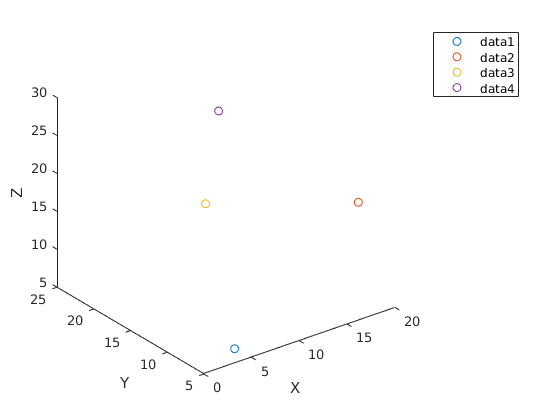

figure;
plot3(a(1),a(2),a(3),'o')
hold on
plot3(b(1),b(2),b(3),'o')
plot3(c(1),c(2),c(3),'o')
plot3(d(1),d(2),d(3),'o')
xlabel('X');
ylabel('Y');
zlabel('Z');
legend('show');
hold off

С вершинами:

a= sym(a)

$$a = \left(\begin{array}{ccc} 4 & 6 & 6 \end{array}\right)$$

b=sym(b)

$$b = \left(\begin{array}{ccc} 20 & 10 & 16 \end{array}\right)$$

c=sym(c)

$$c = \left(\begin{array}{ccc} 14 & 23 & 11 \end{array}\right)$$

d=sym(d)

$$d = \left(\begin{array}{ccc} 10 & 16 & 29 \end{array}\right)$$

syms ('y',[1,3])
syms ('x',[1,3])

Функция плотности:

Rho=sum(x)

$$Rho = x_{1}+x_{2}+x_{3}$$

y;
y = transpose (y);
x = transpose (x);


y;

Матрица отображения из S в W

C_S_V=sym([b'-a',c'-a',d'-a'])

$$C\_S\_V = \left(\begin{array}{ccc} 16 & 10 & 6\\ 4 & 17 & 10\\ 10 & 5 & 23 \end{array}\right)$$

z=C_S_V*y;
vecY=symvar(z);

Свозное отображение из S в V

x=z+a'

$$x = \left(\begin{array}{c} 16\,y_{1}+10\,y_{2}+6\,y_{3}+4\\ 4\,y_{1}+17\,y_{2}+10\,y_{3}+6\\ 10\,y_{1}+5\,y_{2}+23\,y_{3}+6 \end{array}\right)$$

Якобиан

J = det(C_S_V)

$$J = 4636$$

Функция плотности в V

Rho=sum(x)

$$Rho = 30\,y_{1}+32\,y_{2}+39\,y_{3}+16$$

Поочередно спроецируем пирамиду на оси и найдем соответствующие координаты точки центра тяжести cxi


$$c{\mathrm{x}}_i =\frac{I_i }{I}$$



$$I=\int_V f\left(x\right)\mathrm{dx}=\int_0^1 {\mathrm{dy}}_1 \int_0^{1-y_1 } {\mathrm{dy}}_2 \int_0^{1-y_1 -y_2 } \mathrm{Rho}\left(y_! ,y_2 ,y_3 \right){\mathrm{dy}}_3$$



$$I_i =\int_V x_i *f\left(x\right)\mathrm{dx}=\int_0^1 {\mathrm{dy}}_1 \int_0^{1-y_1 } {\mathrm{dy}}_2 \int_0^{1-y_1 -y_2 } x_i *\mathrm{Rho}\left(y_! ,y_2 ,y_3 \right){\mathrm{dy}}_3$$



I1=int(Rho,y3,0,1-y(1)-y(2));
I2=int(I1,y(2),0,1-y(1));
I3=int(I2,y(1),0,1);
I=I3

$$I = \frac{55}{8}$$

double(I)

ans = 6.8750


I1=int(x(1)*Rho,y3,0,1-y(1)-y(2));
I2=int(I1,y(2),0,1-y(1));
I3=int(I2,y(1),0,1);
I1=I3

$$I1 = \frac{5063}{60}$$

double(I3)

ans = 84.3833

cx1=I3/I

$$cx1 = \frac{10126}{825}$$

double(cx1)

ans = 12.2739


I1=int(x(2)*Rho,y3,0,1-y(1)-y(2));
I2=int(I1,y(2),0,1-y(1));
I3=int(I2,y(1),0,1);
I2=I3

$$I2 = \frac{2323}{24}$$

double(I3)

ans = 96.7917

cx2=I3/I

$$cx2 = \frac{2323}{165}$$

double(cx2)

ans = 14.0788


I1=int(x(3)*Rho,y3,0,1-y(1)-y(2));
I2=int(I1,y(2),0,1-y(1));
I3=int(I2,y(1),0,1)

$$I3 = \frac{879}{8}$$

double(I3)

ans = 109.8750


cx3=I3/I

$$cx3 = \frac{879}{55}$$

double(cx3)

ans = 15.9818

xc=[cx1,cx2,cx3]

$$xc = \left(\begin{array}{ccc} \frac{10126}{825} & \frac{2323}{165} & \frac{879}{55} \end{array}\right)$$

xc = double ([cx1,cx2,cx3])

xc =    12.2739   14.0788   15.9818


Нарисуем все вместе

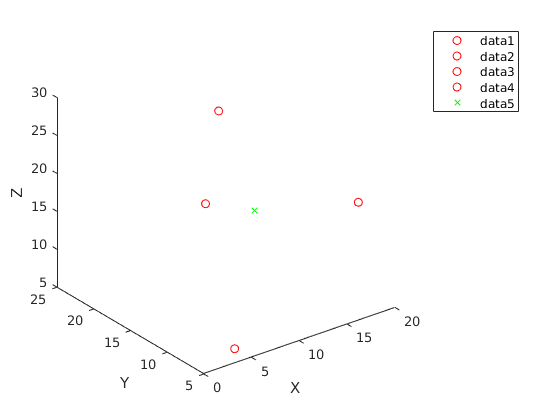

figure;
plot3(a(1),a(2),a(3),'or')
hold on
plot3(b(1),b(2),b(3),'or')
plot3(c(1),c(2),c(3),'or')
plot3(d(1),d(2),d(3),'or')
plot3(xc(1),xc(2),xc(3),'xg')

xlabel('X');
ylabel('Y');
zlabel('Z');
legend('show');
hold off